clear all
clc
n = 12;
datos_linea = [4 5 0.01 1j*0.068 1j*0.0348; 4 6 0.017 1j*0.092 1j*0.0549; 5 7 0.011308 1j*0.02832 1j*0.0317638; 6 9 0.039 1j*0.1738 1j*0.0358; 6 12 0.023 1j*0.18 1j*0.0236; 7 8 0.008477 1j*0.057522 1j*0.158821; 8 9 0.0119 1j*0.1008 1j*0.0209; 10 11 0.031 1j*0.123 1j*0.0123];
datos_trafos = [1 4 10 0.06 0.07 0.025; 2 7 0 0.05 0 0; 3 9 0 0.08 0 0; 11 12 0 0.1 0 0];
disp('Info del sistema')

Info del sistema


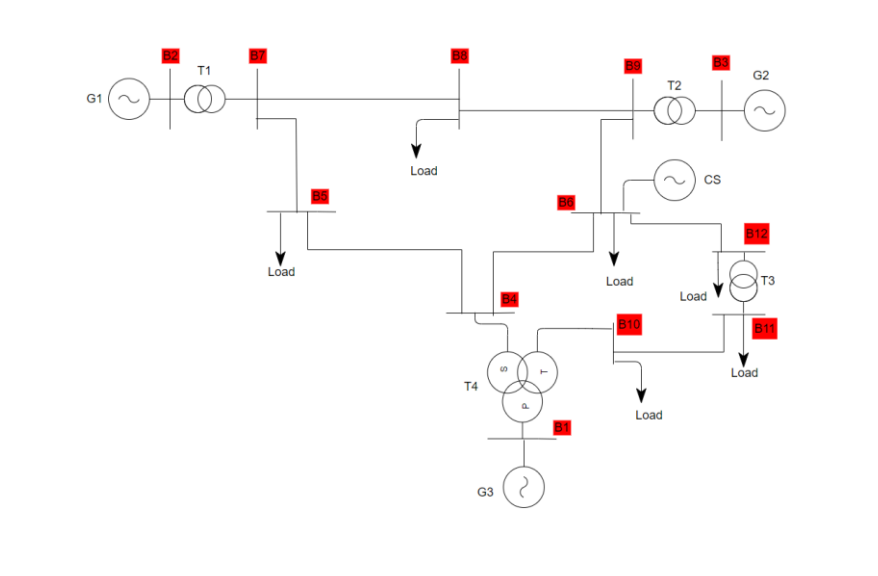

SP = imread('Sistema_potencia_ejp.png');
imshow(SP)

disp('Líneas : ')

Líneas : 


for i = 1:length(datos_linea(:,1))
    l = ['Linea ', num2str(i), ': ', num2str(datos_linea(i,1)), ' - ', num2str(datos_linea(i,2))];
    disp(l)
end

Linea 1: 4 - 5


Linea 2: 4 - 6


Linea 3: 5 - 7


Linea 4: 6 - 9


Linea 5: 6 - 12


Linea 6: 7 - 8


Linea 7: 8 - 9


Linea 8: 10 - 11


disp('Trafos: ')

Trafos: 


for i = 1:length(datos_trafos(:,1))
    if datos_trafos(i,3) ~= 0
        l = ['Trafo tridevanado : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2)), ' - ', num2str(datos_trafos(i,3))];
    else
        l = ['Trafo ', num2str(i), ' : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2))];
    end
    disp(l)
end

Trafo tridevanado : 1 - 4 - 10


Trafo 2 : 2 - 7


Trafo 3 : 3 - 9


Trafo 4 : 11 - 12


Q1 = input('¿Desea desconectar una línea? \n Sí: 1 - No: 2 \n');
if Q1 == 1
    line = input('¿Qué línea desea desconectar?');
    Y_barra = Matriz_Ybarra(datos_linea,n,line)
else
    Y_barra = Matriz_Ybarra(datos_linea,n,false)
end

Y_barra =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.0590 -24.8156i  -2.1169 +14.3946i  -1.9422 +10.5107i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.1169 +14.394